# Lesson I.1:   Vectors, Linear Combinations, Lengths and Angles (F24)

The goal of this lesson is to help the reader fill in gaps between earlier experiences with vectors, mostly in high school algebra and in physics courses, and a modern understanding of applied linear algebra.   Thus, the reader will likely have some familiarity with most of the material of this lesson.  The deep connection among the algebraic, geometric, algorithmic and computational aspects of applied linear algebra is an important theme of the course illustrated throughout this lesson.  

**Vectors. ** The concept of ***vecto***r, basic to linear algebra, is used in many applications.  We begin this course with a simple, bare-bones definition of a vector as an ordered list of numbers.   Commonly, such a concrete vector is written as a vertical column and enclosed in brackets or parentheses.    For the most part, square brackets will be used in these notes; for example,

**Real Vectors of Various Sizes**

$\left[\matrix{1\cr4\cr2}\right],\qquad
\left[\matrix{\pi\cr \sqrt{2} \cr 7}\right], \qquad
\left[\matrix{0\cr0}\right],\qquad
\left[\matrix{1\cr2\cr3\cr4\cr}\right],\qquad
\left[\matrix{x_1\cr x_2\cr x_3 \cr x_4\cr x_5 \cr x_6}\right],\qquad
\left[\matrix{4}\right]
$.

Notice that the number of ***entries*** or ***components ***of a concrete vector may be any positive integer (including 1).  In the examples above, the components are all real numbers.  The set of all vectors having $n$ real components is denoted ${\mathbb R}^n$.  (The set of all real numbers is denoted ${\mathbb R}$; for practical purposes, ${\mathbb R}$ and ${\mathbb R}^1$can be considered to be the same set.)   When using symbols to denote a vector, we often adopt the common practice from the physical sciences of indicating a vector with a boldface font, an overbar or an overarrow such as 

${\bf x},~{\bf a},~{\bf u}$, $\bar x,~\bar a,~\bar u, ~\overrightarrow{x}, ~\overrightarrow{a},~\overrightarrow{u}.$

__________________________________________________________________________

The MATLAB software package provides the means to enter and manipulate real vectors.   The simplest way to enter such a vectors is to enclose the entries in square brackets and separate them with semicolons:

[1; 4; 2]

Notice that in its numerical mode MATLAB does not print brackets or parenthesis around the entries of the vector.   In symbolic mode, however, MATLAB does provide parenthesis in LiveScripts such as this document:

[sym(pi); sym(sqrt(2)); 7]  % pi and sqrt(2) made to be to symbolic values
syms x1 x2 x3 x4 x5 x6;     % indexed components of x made into symbolic values
[x1; x2; x3; x4; x5; x6]

Reference to the $\ell^{\text{th}}$ entry of a vector are typically made with a subscript affixed to the name of the vector in italics rather than boldface as in "$x_2$ is the second component of ${\bf x}=\left[\matrix{x_1\cr x_2}\right]$."   In MATLAB, parenthesis are generally used to indicate specific components of vectors.

x=[4;5;6]
x(3)
x(2)=7
x([1 2])     % MATLAB allows access to more than one component at a time

_____________________________________________________________

Due to the Fundamental Theorem of Algebra (FTA) and the needs of many applications, it is necessary to consider vectors with complex entries such those shown below:

**Complex Vectors of Various Sizes**

$\left[\matrix{1+3i\cr4+2i\cr2i}\right],\qquad
\left[\matrix{\pi\big(\frac32+\frac13i\big)\cr i\sqrt{2} \cr e^{\pi i}}\right], \qquad
\left[\matrix{0\cr0}\right],\qquad
\left[\matrix{1\cr2i\cr-3\cr-4i\cr}\right],\qquad
\left[\matrix{z_1\cr z_2\cr z_3 \cr z_4\cr z_5 \cr z_6}\right],\qquad
\left[\matrix{j}\right]
$.

The set of all vectors with $n$ complex components is denoted ${\mathbb C}^n$.   The set of all complex numbers is denoted ${\mathbb C}$.   Since the real numbers are naturally considered a subset of the complex numbers (${\mathbb R}\subset{\mathbb C}$), we generally consider ${\mathbb R}^n\subset{\mathbb C}^n$.   

__________________________________________________________________________

MATLAB is well versed in complex numbers including the use, in many fields of study, of $j$ (instead of $i$) as the square root of -1.

[1+3*i; 4+2*i; 2*j]
[sym(pi*(3/2+i/3)); sym(i*sqrt(2)); exp(i*sym(pi))]

MATLAB is even aware of Euler's formula:   $e^{i\theta}=\cos\theta~+~i\sin\theta$.

__________________________________________________________________________

There are other kinds of numbers from which vectors, and later matrices, can be constructed.   In the abstract theory of linear algebra, the set of "numbers" from which components of vectors can be drawn need only satisfy the "field axioms" which are essentially the basic rules of  high school algebra regarding addition, subtraction, multiplication and division.    Many such sets of numbers, known as mathematical fields, are, like the real numbers, subfields of the complex numbers.   An interesting exception, the finite fields, are significant in discrete math but unfortunately beyond the scope of this course.    In this course, we focus on ${\mathbb R}^n$ and ${\mathbb C}^n$ as the concrete manifestations of the abstract concept of vector spaces.   When we consider matters for which the distinction between real and complex numbers is not of particular importance, we may use the notation ${\mathbb F}^n$ where ${\mathbb F}$ may be either field.

A few vectors are commonly used and therefore have special names.    The ***zero vector*** in ${\mathbb F}^n$ (denoted ${\bf 0}$) is the vector having all its components equal to zero.

        (I1.1a)        ${\bf 0}=\left[\matrix{0\cr 0\cr \vdots \cr 0}\right]$.

The $\ell^{\text{th}}$***standard basis vector*** in ${\mathbb F}^n$ (denoted ${\bf e}_\ell$) is the vector having all components equal to zero except for the $\ell^{\text{th}}$component which equals one.  The four standard basis vectors in ${\mathbb F}^4$ are 

        (I1.1b)        ${\bf e}_1=\left[\matrix{1\cr 0 \cr 0 \cr 0}\right],\qquad
{\bf e}_2=\left[\matrix{0\cr1\cr 0 \cr 0}\right],\qquad
{\bf e}_3=\left[\matrix{0\cr 0 \cr 1 \cr 0}\right],\qquad
{\bf e}_4=\left[\matrix{0\cr0\cr 0 \cr 1}\right].$

_____________________________________________________________

**Graphical representation of vectors.   **As defined above, vectors are simply lists of numbers without any specific geometrical meaning.  These vectors can be useful in applications where geometry is irrelevant.   For example, the components of a vector might represent the number of hours that the various employees of a corporation have worked during the week or the weights of a list of patients.    In many applications, however, vectors represent the Cartesian coordinates of points in a plane or space.  For such vectors, graphical representation is particularly useful.    We consider two approaches to graphical representation:  "dots" and "arrows."    The "dots" approach marks the Cartesian coordinates of a point with a dot.   For example, the vectors $\left[\matrix{1\cr \pi}\right],~
\left[\matrix{-2\cr -3}\right],~
\left[\matrix{-1\cr 0}\right],~\text{and}~
\left[\matrix{\sqrt{2}\cr-3/2}\right]$are plotted with dots below in Figure I1.1.

figI1_1()

ans =      1
     4
     2


Notice the use of an alternative notation for vectors where the components are written horizontally (from left to right) and surrounded by rounded parentheses with the components separated by commas.   This notation is often used in graphs, but also finds use in other situations (especially to save space on the printed page).

**Alternative Notations for Vectors in** ${\mathbb F}^n$


$$(x_1,x_2,\dots,x_n)=\left[\matrix{x_1\cr x_2\cr\vdots\cr x_n}\right]$$


Vectors are often used to represent the offset or displacement between two points.    Hence, they are sometimes plotted as an arrow from one point to another.    Although any two points might be used, a standard approach to plotting the vector ${\bf x}=(x_1,x_2,\dots,x_n)$ is to represent it by the arrow from the zero vector to ${\bf x}$.  

figI1_2()

_____________________________________________________________

**Vector operations.   **For vectors, both concrete and abstract, there is one principal operation:  ***formation of linear combinations.***   This operation is generally described in terms of two simpler operations:  ***vector addition*** and ***scalar multiplication***.   For concrete vectors, i.e. vectors in ${\mathbb R}^n$ or ${\mathbb C}^n$, vector addition is accomplished by adding corresponding components of the vectors:

        (I1.2a)        ${\bf x} = \left[\matrix{x_1\cr x_2\cr \vdots \cr x_n}\right]\qquad\text{and}\qquad
{\bf y} = \left[\matrix{y_1\cr y_2\cr \vdots \cr y_n}\right]\qquad\Rightarrow\qquad
{\bf x}+{\bf y}= \left[\matrix{x_1+y_1\cr x_2+y_2\cr \vdots \cr x_n+y_n}\right]$

Notice that the two vectors must have the same number of components for the sum of the vectors to be defined.    Geometrically, two vectors ${\bf x}$ and ${\bf y}$ (plotted in blue below) form an angle.   If the vectors are displaced to begin at the end of the other vector (plotted in green below) then the two original vectors and the two displaced vectors form the sides of a parallelogram.    The sum of the two vectors ${\bf x}+{\bf y}$ is the vector represented by the arrow from the origin to the opposite corner of the parallelogram (plotted in red below).

figI1_3()

$$ans = \left(\begin{array}{c} \pi \\ \sqrt{2}\\ 7 \end{array}\right)$$

For concrete vectors, scalar multiplication combines a ***scalar*** (a number) $\alpha$ and a vector by multiplying each component of the vector ${\bf x}$ by the scalar:

        (I1.2b)        $\alpha {\bf x}~=~\alpha \left[\matrix{x_1\cr x_2\cr \vdots \cr x_n}\right]~=~\left[\matrix{\alpha x_1 \cr \alpha x_2 \cr \vdots \cr \alpha x_n}\right]$.

Geometrically, scalar multiplication can be thought of as stretching or shrinking the vector by the factor of $\alpha$. 

figI1_3b()

Vector addition and scalar multiplication, when combined together, are known as formation of a ***linear combination.***   Specifically, if $\{{\bf x}_1, {\bf x}_2,\dots,{\bf x}_p\}\subset {\mathbb F}^n$ and $\{\alpha_1,\alpha_2,\dots,\alpha_p\}\subset {\mathbb F}$ then 


$$\alpha_1{\bf x}_1~+~\alpha_2{\bf x}_2~+~ \cdots ~+~ \alpha_p{\bf x}_p$$


is the general form of a linear combination of the set of vectors $\{{\bf x}_1, {\bf x}_2,\dots,{\bf x}_p\}$.   This deceptively simple mathematical construction is the basis for most of the significant questions in the first half of this course.

**Lecturecise I1.1:**   Show that each vector in the set $\left\{{\bf x}_1,{\bf x}_2,{\bf x}_3\right\}$ is a linear combination of the other two vectors in the set.


$${\bf x}_1=\left[ \matrix{1\cr2\cr3} \right], \qquad
{\bf x}_2=\left[\matrix{4\cr5\cr6}\right], \qquad
{\bf x}_3=\left[\matrix{7\cr8\cr9}\right].$$


From the easily checked observation ${\bf x}_2=\frac12({\bf x}_1+{\bf x}_3)$, 


$${\bf x}_1=2{\bf x}_2-{\bf x}_3,\qquad
{\bf x}_2=\frac12 {\bf x}_1 + \frac12{\bf x}_3,\quad\text{and}\quad
{\bf x}_3=2{\bf x}_2-{\bf x}_1.$$


**Lecturecise I1.2:**   Show that none of the vectors in the set $\left\{{\bf e}_1,{\bf e}_2,{\bf e}_3\right\}$ is a linear combination of the other two vectors in the set.


$${\bf e}_1=\left[ \matrix{1\cr0\cr0} \right], \qquad
{\bf e}_2=\left[\matrix{0\cr1\cr0}\right], \qquad
{\bf e}_3=\left[\matrix{0\cr0\cr1}\right].$$


Suppose that ${\bf e}_1$ is a linear combination of $\left\{ {\bf e}_2,{\bf e}_3\right\}$, i.e., ${\bf e}_1=\alpha {\bf e}_2+\beta {\bf e}_3$, then

$\left[\matrix{1\cr 0\cr 0}\right]=\alpha \left[\matrix{0\cr 1\cr 0}\right]+\beta\left[\matrix{0\cr 0\cr 1}\right]=\left[\matrix{0 \cr\alpha\cr\beta}\right]$.

But the first component of this vector equation is $1=0$ which is of course false.   Hence, the supposition that ${\bf e}_1$ is a linear combination of $\left\{ {\bf e}_2,{\bf e}_3\right\}$ is false.   Similarly, it can be shown that neither ${\bf e}_2$ nor ${\bf e}_3$ is a linear combination of the other two vectors in the set.

**Span.**  The ***span ***is a central concept in linear algebra that associates a generally finite set of vectors $S=\{{\bf x}_1,\dots,{\bf x}_p\}$ to a generally infinite set of vectors, the span of $S$ which is written $\text{span}(S)$, that can be viewed as constituting a geometric object such as a line or a plane.   In this course, it turns out that every span can be identified with another central concept:  the ***subspace ***(a set of vectors closed under formation of linear combinations).   The ***span*** of a set of a nonempty set of vectors $\{{\bf x}_1, {\bf x}_2,\dots,{\bf x}_p\}$ is the set of all linear combinations of the vectors in the set.    For the empty set $\emptyset\subset{\mathbb F}^n$, the span is defined to be the singleton set containing the zero vector:

        (I1.3)        $\text{span}(\emptyset)=\{{\bf 0}\}=\left\{\left[\matrix{0\cr 0\cr \vdots \cr 0}\right]\right\}$.

Developing a sense of the geometric nature of the span of a set of vectors can prove helpful for gaining intuition regarding a span.    Consider a set $S\subset {\mathbb R}^2$ containing a single nonzero vector ${\bf x}=(3,4)$.   For a singleton set, the span consists of all multiples of the one vector in the set.   Hence, $\text{span}(S)$ includes the vectors and infinitely many more.    Geometrically, the span of a singleton set containing a nonzero vector ${\bf x}$ is the line passing through ${\bf x}$ and the origin ${\bf 0}$.

figI1_4()

$$ans = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3}\\ x_{4}\\ x_{5}\\ x_{6} \end{array}\right)$$

**Lecturecise I1.3:**   What are the common names for the spans of each of the following set of vectors.

        (a)    $\left\{\left[\matrix{1\cr0\cr0}\right]\right\}$        (b)     $\left\{\left[\matrix{1\cr0\cr0}\right],\left[\matrix{0\cr1\cr0}\right]\right\}$         (c)     $\left\{\left[\matrix{1\cr0\cr-1}\right],\left[\matrix{1\cr0\cr1}\right]\right\}$          (d)     $\left\{\left[\matrix{1\cr0\cr0}\right],\left[\matrix{0\cr1\cr0}\right],\left[\matrix{0\cr0\cr1}\right]\right\}$.

Solution:   (a) the x-axis, (b) the xy-plane, (c) the xz-plane $\left(\left[\matrix{x \cr 0 \cr z}\right]=\frac{x-z}2\left[\matrix{1\cr 0 \cr -1}\right]+\frac{x+z}2\left[\matrix{1\cr 0\cr 1}\right]\right)$, (d)  three-dimensional space.

**Lecturecise I1.4:**   Determine which of the numbered predicates are true.

The span of a set of vectors $S$

- is a non-empty set of vectors,

- contains $S$,

- is infinite when $S$ is a nonempty set containing at least one nonzero vector,

- is unbounded when $S$ is a nonempty set containing at least one nonzero vectors,

- contains the zero vector, 

- is closed under the formation of linear combinations (i.e., forming a linear combination of vectors from $\text{span}(S)$always results in a vector in $\text{span}(S)$).

All are true.

**Major questions about linear combinations.**   Some questions about linear combinations are fundamental to linear algebra and its applications.   While we do provide some partial solutions to some of these questions, more complete answers are developed throughout the course.    

**Major question 1 (membership in a span):**    Given ${\bf x}\in {\mathbb F}^n$ and $S=\{{\bf a}_1,\dots,{\bf a}_k\}\subset {\mathbb F}^n$, is ${\bf x}\in\text{span}(S)$?

To answer this question in the affirmative, we must show that there are coefficients $\alpha_1,\dots,\alpha_k$ such that ${\bf x}=\alpha_1{\bf a}_1+\cdots+\alpha_k{\bf a}_k$.   The key observation for this demonstration is generally that the coefficients must satisfy the linear system of equations:

                (I1.6)                $\left\{\matrix {
A_{11}\alpha_1&+&\cdots&+&A_{1k}\alpha_k &=& x_1 \cr
\vdots &&&&\vdots & & \vdots \cr
A_{n1}\alpha_1&+&\cdots&+&A_{nk}\alpha_k&=&x_k}$

where $A_{ij}$ is the $i^{\text{th}}$ component of ${\bf a}_j$.

**Lecturecise I1.5:   **Show that 

            $\left[\matrix{1\cr1\cr1}\right]=\alpha_1 \left[\matrix{1\cr2\cr 3}\right]~+~\alpha_2\left[\matrix{4\cr5\cr 6}\right]~+~\alpha_3\left[\matrix{7\cr8\cr9}\right]$    if and only if     $\left\{ \matrix{
1\alpha_1 &+&4\alpha_2&+&7\alpha_3=1\cr
2\alpha_1&+&5\alpha_2&+&8\alpha_3=1\cr
3\alpha_1&+&6\alpha_2&+&9\alpha_3=1\cr
}
$.

This merely requires evaluating the linear combination in the first expression:

        $\alpha_1 \left[\matrix{1\cr2\cr 3}\right]~+~\alpha_2\left[\matrix{4\cr5\cr 6}\right]~+~\alpha_3\left[\matrix{7\cr8\cr9}\right]~=~
\left[\matrix{1\alpha_1 \cr 2\alpha_1\cr 3\alpha_1}\right]~+~\left[\matrix{4\alpha_2\cr 5 \alpha_2 \cr 6\alpha_2}\right]~+~\left[\matrix{7\alpha_3\cr 8\alpha_3\cr 9\alpha_3}\right]=\left[\matrix{
1\alpha_1~+~4\alpha_2~+~7\alpha_3\cr 
2\alpha_1~+~6\alpha_2~+~8\alpha_3\cr
3\alpha_1~+~6\alpha_2~+~9\alpha_3\cr 
}\right]=\left[\matrix{1\cr1\cr1}\right]$.

In the coming few lessons, we will determine methods for completely solving all such systems of linear equations and thus give a complete answer to this first major question.

**Major question 2 (computation of expansion coefficients):**    Given ${\bf x}\in \text{Span}\big(\{{\bf a}_1,\dots,{\bf a}_k\}\big)$, determine the expansion coefficients $\alpha_1,\dots,\alpha_k$ such that ${\bf x}=\alpha_1{\bf a}_1+\cdots+\alpha_k{\bf a}_k$.   

This question is closely related to the first.   The first is equivalent to determining if solutions to (I1.6) exist while the second is equivalent to computing solutions.    The method of coming lessons, Gaussian elimination, settles both questions conclusively.    

**Lecturecise I1.6:**   Find and solve the linear system for the coefficients $\alpha_1$ and $\alpha_2$ such that 

                 $\left[\matrix{3\cr 4}\right]~=~\alpha_1\left[\matrix{1\cr 1}\right]~+~
\alpha_2\left[\matrix{1\cr -1}\right]$.

Adding and subtracting the equations in the linear system 

                $\left\{ \matrix{1\alpha_1&+&1\alpha_2&=&3 \cr
1\alpha_1&-&1\alpha_2&=&4}\right.
\quad\Rightarrow\quad
\left\{\matrix{2\alpha_1&+&0\alpha_2&=&7 \cr
0\alpha_1&+&2\alpha_2&=&-1}\right.
\quad\Rightarrow\quad
\left\{\matrix{\alpha_1&=&7/2\cr
\alpha_2&=&-1/2}\right.
$.

**Major question 3 (uniqueness of expansion coefficients):   **Given ${\bf x}\in \text{Span}\big(\{{\bf a}_1,\dots,{\bf a}_k\}\big)$determine if there is more than one set of coefficients $\alpha_1,\dots,\alpha_k$ such that ${\bf x}=\alpha_1{\bf a}_1+\cdots+\alpha_k{\bf a}_k$.    This question too will be settled by the Gaussian elimination-based theory.

**Lecturecise I1.7:**   Show that there are at least two choices of coefficients that solve the problem given in Lecturecise I1.5.

         $\left[\matrix{1\cr1\cr1}\right]=\frac13\left(\left[\matrix{4\cr 5\cr 6}\right]-\left[\matrix{1\cr 2\cr 3}\right]\right)+\alpha \left(\matrix{\left[\matrix{1\cr2\cr3}\right]-2\left[\matrix{4\cr 5\cr 6}\right]+\left[\matrix{7\cr 8\cr 9}\right]}\right)~=~
(\alpha-\frac13) \left[\matrix{1\cr2\cr3}\right]~+~(\frac13-2\alpha)\left[\matrix{4\cr5\cr6}\right]~+~\alpha\left[\matrix{7\cr 8\cr 9}\right]$    for all values of $\alpha$.

**Major question 4 (choice of basis):   **The final question is less specific and not addressed in much depth until the last third of the course:   Given a span $\text{Span}\big(\{{\bf a}_1,\dots,{\bf a}_k\}\big)$, is there an alternative set of vectors $\{{\bf b}_1,\dots,{\bf b}_p\}$having the same span, i.e., $\text{Span}\big(\{{\bf a}_1,\dots,{\bf a}_k\}\big)=
\text{Span}\big(\{{\bf b}_1,\dots,{\bf b}_p\}\big)$, and which better represents that span for the application at hand.    

What "better represents" means depends on the details of the application.    As a simple introductory example, consider the sets $A=\{{\bf a}_1,{\bf a}_2,{\bf a}_3\}$and $B=\{{\bf b}_1,{\bf b}_2\}$ where

                
$$
{\bf a}_1=\left[\matrix{1\cr2\cr3}\right],\qquad
{\bf a}_2=\left[\matrix{4\cr5\cr6}\right],\qquad
{\bf a}_3=\left[\matrix{7\cr8\cr9}\right],\qquad
{\bf b}_1=\left[\matrix{1\cr1\cr1}\right],\qquad
{\bf b}_2=\left[\matrix{1\cr0\cr-1}\right].
$$


From the observations that ${\bf a}_1=2{\bf b}_1-1{\bf b}_2$, ${\bf a}_2=5{\bf b}_1-1{\bf b}_2$, ${\bf a}_3=8{\bf b}_1-1{\bf b}_2$ ${\bf b}_1=\frac13({\bf a}_2-{\bf a}_1)$, and ${\bf b}_2=\frac13({\bf a}_3-4{\bf a}_4)$, it follows that $\text{Span}(A)=\text{Span}(B)$ since

        $\alpha_1 {\bf a}_1+\alpha_2{\bf a}_2+\alpha_3{\bf a}_3=(2\alpha_1+5\alpha_2+8\alpha_3){\bf b}_1+(-\alpha_1-\alpha_2-\alpha_3){\bf b}_2$    and 

       $\beta_1{\bf b}_1+\beta_2{\bf b}_2=-(\frac13\beta_1+\frac43\beta_2){\bf a}_1+\frac13\beta_1{\bf a}_2+\frac13\beta_2{\bf a}_3$.

While it is ultimately a matter of opinion, it is arguable that $B$ better represents the span as the smaller number of vectors simplifies the representation.

**Lecturecise I1.8:   **Let $C=\{{\bf c}_1,{\bf c}_2\}$ and $D=\{{\bf d}_1,{\bf d}_2\}$ where ${\bf c}_1=\left[\matrix{1\cr 1}\right], 
{\bf c}_2=\left[\matrix{1\cr -1}\right],
{\bf d}_1=\left[\matrix{1\cr 0}\right], 
{\bf d}_2=\left[\matrix{0\cr 1}\right].
$   Show that $\text{Span}(C)=\text{Span}(D)$.   Which set "best" represents the span?

$\text{Span}(C)=\text{Span}(D)$ since $\alpha_1{\bf c}_1+\alpha_2{\bf c}_2 =(\alpha_1+\alpha_2){\bf d}_1+(\alpha_2-\alpha_2){\bf d}_2$ and $\beta_1 {\bf d}_1+\beta_2{\bf d}_2= \frac12(\beta_1+\beta_2){\bf c}_1+\frac12(\beta_1-\beta_2){\bf c}_2$.

While it is again a matter of opinion, it is reasonable to prefer $D$ as the computation of expansion coefficients is so simple:

${\bf x}=\left[\matrix{x_1\cr x_2}\right]=x_1{\bf d}_1+x_2{\bf d}_2$.

**Affine combinations.   **An ***affine combination*** of a set of vectors is a linear combination of the vectors where the sum of the coefficients equals 1.     

**Lecturecise I1.9:**  Determine which of the vectors are affine combinations of the set $\{{\bf x},{\bf y}\}$ where ${\bf x}=\left[\matrix{1\cr 2}\right]$and ${\bf y}=\left[\matrix{3\cr 2}\right]$:

    (a)   ${\bf z}_1=\left[\matrix{1\cr 1}\right]$        (b)   ${\bf z}_2=\left[\matrix{2\cr 2}\right]$       (c)   ${\bf z}_3=\left[\matrix{1\cr 2}\right]$       (d)   ${\bf z}_4=\left[\matrix{3\cr 2}\right]$       (e)   ${\bf z}_5=\left[\matrix{6/5\cr 2}\right]$       (f)   ${\bf z}_1=\left[\matrix{5\cr 2}\right]$.

All but ${\bf z}_1$ are affine combinations:

    (b)   ${\bf z}_2=\frac12{\bf x}+\frac12{\bf y}$       (c)   ${\bf z}_3=1{\bf x}+0{\bf y}$       (d)   ${\bf z}_4=0{\bf x}+1{\bf y}$       (e)   ${\bf z}_5=\frac9{10}{\bf x}+\frac{1}{10}{\bf y}$       (f)   ${\bf z}_5=(-1){\bf x}+2{\bf y}$.

Plotting the points in Lecturecise I1.9 is instructive.

figI1_5()

Geometrically, the affine combinations of the set $\{{\bf x},{\bf y}\}$ form a line through the points ${\bf x}$ and ${\bf y}$.   More generally, the set of all affine combination of two distinct points is the line through the two points.    Similarly, the affine combination of three points (which are not colinear) is the plane through the three points.    Moreover, this observation generalizes to any (finite) number of points though we lack commonly used geometric language for these higher dimensional objects.   Linear algebra provides a means for using understanding and intuition from lower dimensional geometric objects for higher dimensional objects.

**Thought question:**    The intersection of two planes in three-dimensional space is either the empty set, a line or a plane.    Why is it impossible for two planes in ${\mathbb R}^3$ to intersect in a single point?

**Algebraic properties of vectors.     **Vector addition and scalar multiplication have simple and rather obvious properties that together are known at the vector space axioms.   

            (I1.7a)        ${\bf x}+{\bf y}={\bf y}+{\bf x}$                         

            (I1.7b)        $({\bf x+\bf  y})+{\bf z}={\bf x+(\bf  y}+{\bf z})$        

            (I1.7c)        ${\bf 0}+{\bf x}={\bf x}$                                

            (I1.7d)        ${\bf x}+(-{\bf x})={\bf 0}$                            

            (I1.7e)       $\alpha(\beta{\bf x})=(\alpha\beta){\bf x}$                        

            (I1.7f)        $1{\bf x}={\bf x}$

            (I1.7g)        $0{\bf x}={\bf 0}$

            (I1.7h)        $\alpha({\bf x}+{\bf y})=\alpha{\bf x}+\beta{\bf y}$

            (I1.7i)         $(\alpha+\beta){\bf x}=\alpha{\bf x}+\beta{\bf x}$

The first four axioms concern the properties of vector addition (commutativity, associativity, additive identity, additive inverse).   The next three axioms concern the consistency of scalar multiplication with vector addition (specifically, the truth of sensible statements such as ${\bf x}+{\bf x}+{\bf x}=3{\bf x}$).  The last two axioms assure that reasonable distributive laws are in place.   All the basic properties of vector spaces follow from these axioms.

**Lecturecise I1.10:  ** Show that ${\bf x}+{\bf x}=2{\bf x}$.

        
$$\matrix{
{\bf x}+{\bf x} &=& 1{\bf x}+1{\bf x} &\qquad&\text{based on (I1.7f)}\qquad \cr
&=&(1+1){\bf x} &\qquad&\text{based on  (I1.7i)}\qquad \cr
&=&2{\bf x} &&\text{based on }~ 1+1=2~
}$$


**The dot product.    **The dot product of two vectors is a simple but hugely important operation on vectors having important geometric significance.    We begin with real vectors:   If ${\bf x}$ and ${\bf y}$ are vectors in ${\mathbb R}^n$, then the dot product ${\bf x}\cdot{\bf y}$ is a real value given by

        (I1.8)        ${\bf x}\cdot{\bf y}~=~\sum_{\ell=1}^n x_\ell y_\ell~=~x_1y_1+x_2y_2+\cdots+x_ny_n$.

The inner product provides a tool for measuring distances and angles.   The **norm **or **length **of a vector ${\bf x}\in {\mathbb R}^n$ is determined by the dot product:

         (I1.9)        $||{\bf x}||~=~\sqrt{ {\bf x}\cdot{\bf x}}~=~x_1^2+x_2^2+\cdots+x_n^2$ .    

figI1_6()

x =      4
     5
     6


The angle $\theta$ between two vectors ${\bf x}$ and ${\bf y}$can be determined through the dot product:

        (I1.10)        ${\bf x}\cdot{\bf y}=||{\bf x}||\, ||{\bf y}||\,\cos\theta$.

figI1_7()

ans = 6

Three important properties of the dot product are

- Linearity:  $(\alpha{\bf x}+\beta{\bf y})\cdot{\bf w}=\alpha{\bf x}\cdot{\bf w}+\beta{\bf y}\cdot{\bf w}$,

- Symmetry:   ${\bf x}\cdot{\bf y}={\bf y}\cdot{\bf x}
$,

- Positivity:   ${\bf x}\cdot{\bf x}\ge 0~\text{with equality only if}~{\bf x}={\bf 0}$.

Later, the dot product is extended so that $\mathbb{C}^n$ is satisfies a suitably modified version of these three properties.

From the three properties of the dot product, it is possible to derive the basic properties of the norm:

- Homogeneity:  $||\alpha {\bf x}||=|\alpha|\,||{\bf x}||$

- Positivity:  $||{\bf x}||\ge0$

- Triangle inequality:  $||{\bf x}+{\bf y}||\le||{\bf x}||+||{\bf y}||$

**The Cauchy-Schwarz inequality.    **For ${\bf x}$ and ${\bf y}$ in ${\mathbb R}^n$,

            (I1.11)            $|{\bf x}\cdot{\bf y}|~\le~||{\bf x}||\, || {\bf y}||$.

**Proof of the Cauchy-Schwarz inequality:   ** If $||{\bf x}||=0$ or $||{\bf y}||=0$, then (I1.11) follows immediately.   Suppose  $||{\bf x}||\ne0$ and $||{\bf y}||\ne0$, and consider the unit vectors pointing in the directions of ${\bf x}$ and ${\bf y}$:  $\hat{\bf x}=\frac{1}{||{\bf x}||}{\bf x}$ and $\hat{\bf y}=\frac{1}{||{\bf y}||}$.  We begin with the obvious fact that the square of the length of the sum and difference of these two unit vectors is nonnegative:  

        (I1.12a)        $0\le||\hat {\bf x}\pm\hat{\bf y}||^2=(\hat{\bf x}\pm\hat{\bf y})\cdot(\hat{\bf x}\pm\hat{\bf y})=\hat{\bf x}\cdot\hat{\bf x}\pm2\hat{\bf x}\cdot\hat{\bf y}+\hat{\bf y}\cdot\hat{\bf y}=2\pm2\hat{\bf x}\cdot\hat{\bf y}$

since $\hat{\bf x}\cdot\hat{\bf x}=\hat{\bf y}\cdot\hat{\bf y}=1$.  Hence,

        (I1.12b)        $0\le1\pm \hat{\bf x}\cdot\hat{\bf y}\quad\Rightarrow\quad
\mp \hat{\bf x}\cdot\hat{\bf y}\le1\quad\Rightarrow\quad |\hat{\bf x}\cdot\hat{\bf y}|\le1$.

And,

        (I1.12c)        $\Rightarrow\quad \left|\frac{1}{||{\bf x}||\,||{\bf y}||}{\bf x}\cdot{\bf y}\right|\le1\quad\Rightarrow\quad
|{\bf x}\cdot{\bf y}|\le||{\bf x}||\,||{\bf y}||$.

**Follow-up Problems.**

**Problem I1.1:**  Simplify.

    (a)  $3\left[\matrix{1\cr2\cr3}\right]-2\left[\matrix{1\cr1\cr1}\right]$        (b)    $2\left[\matrix{1\cr 2\cr1\cr 3}\right]+2\left[\matrix{3\cr i\cr -1 \cr \frac12}\right]$        (c)    $\left[\matrix{1\cr 2}\right]-3\left[\matrix{1\cr 2 \cr 3}\right]$

**Problem I1.2:  **Describe the following sets.

    (a)    $\text{span} \left\{ \left[\matrix{1\cr 1}\right]\right\}$        (b)    $\text{span}\left\{\left[\matrix{1\cr 1}\right],\left[\matrix{1\cr -1}\right]\right\}$        (c)    $\text{span}(\emptyset)$        (d)    $\text{span}\left\{\left[\matrix{1\cr 1}\right],\left[\matrix{2\cr2}\right]\right\}$

**Problem I1.3:  **For each vector equation determine all values of the coefficients making the equation true.

    (a)    $\left[\matrix{3\cr 7}\right]=\alpha_1\left[\matrix{1\cr 0}\right]+\alpha_2\left[\matrix{0\cr 1}\right]$        (b)    $\left[\matrix{3\cr 7}\right]=\alpha_1\left[\matrix{1\cr 0}\right]+\alpha_2\left[\matrix{1\cr 1}\right]$        (c)    $\left[\matrix{1\cr -1}\right]=\alpha_1\left[\matrix{1\cr 1}\right]+\alpha_2\left[\matrix{-1\cr -1}\right]$        (d)    $\left[\matrix{0\cr 0}\right]=\alpha_1\left[\matrix{1\cr 1}\right]+\alpha_2\left[\matrix{-1\cr -1}\right]$        

**Problem I1.4:  **Use the properties of vector operations and the dot product to show (a) the triangle inequality

                
$$||{\bf x}+{\bf y}|| \le || {\bf x}||+||{\bf y}||$$


and (b) the following polarization identity (identity relating the dot product to the norm)

                 ${\bf x}\cdot{\bf y}=\frac{||{\bf x}+{\bf y}||^2-||{\bf x}-{\bf y}||^2}{4}$.

**Problem I1.5:  **A set of vectors is called a *subspace* iff every linear combination of vectors in the set is also in the set.   For each set below, plot the set and determine if it is a subspace of ${\mathbb R}^2$.   

    (a)    $\left\{ \left[\matrix{x\cr 0}\right]~:~x\in{\mathbb R}\right\}$        (b)    $\text{span}\left\{\left[\matrix{1\cr -2}\right],\left[\matrix{-1\cr -2}\right] \right\}$        (c)    $\left\{ \left[\matrix{x\cr1}\right]~:~x\in{\mathbb R}\right\}$        (d)    $\left\{\left[\matrix{x\cr y}\right]~:~x^2+y^2=1\right\}$

**Problem I1.6:  **A set of vectors is *affine* iff every affine combination of vectors in the set is also in the set.   For each set below, plot the set and determine if it is affine.   

    (a)    $\left\{ \left[\matrix{x\cr 0}\right]~:~x\in{\mathbb R}\right\}$        (b)    $\text{span}\left\{\left[\matrix{1\cr -2}\right],\left[\matrix{-1\cr -2}\right] \right\}$        (c)    $\left\{ \left[\matrix{x\cr1}\right]~:~x\in{\mathbb R}\right\}$        (d)    $\left\{\left[\matrix{x\cr y}\right]~:~x^2+y^2=1\right\}$

**Problem I1.7:  **A set of vectors is a *lattice *iff the sum and difference of every pair of vectors in the set is also in the set and the number of points within a distance of 1 from the origin is finite.    Plot (a portion) of the lattice consisting of all linear combinations of $\left[\matrix{2\cr1}\right]$ and $\left[\matrix{-1\cr 1}\right]$ having integer coefficients.

**Problem I1.8:   **The proof for the Cauchy-Schwarz inequality presented in this lesson is purely algebraic.   Nonetheless, it can be viewed geometrically.   Verify geometrically that if the angle between two nonzero vectors ${\bf x}$ and ${\bf y}$ is $\theta$ then

    (a)    $\cos(\theta)=\hat{\bf x}\cdot\hat{\bf y}$        (b)    $\sin(\theta/2)=\frac12||\hat{\bf x}-\hat{\bf y}||$        (c)     $\cos(\theta/2)=\frac12||\hat{\bf x}+\hat{\bf y}||$.

function figI1_1()

x =      4
     7
     6


d=0.1;

ans =      4
     7


L=4;
x1=[1; pi];
x2=[-2; -3];
x3=[-1; 0];
x4=[sqrt(2); -3/2];
axis([-L L -L L])
hold on
plot([-L L],[0 0],'k:')

ans =    1.0000 + 3.0000i
   4.0000 + 2.0000i
   0.0000 + 2.0000i


plot([0 0],[-L L],'k:')

$$ans = \left(\begin{array}{c} \pi \,\left(\frac{3}{2}+\frac{1}{3}\,\mathrm{i}\right)\\ \sqrt{2}\,\mathrm{i}\\ -1 \end{array}\right)$$

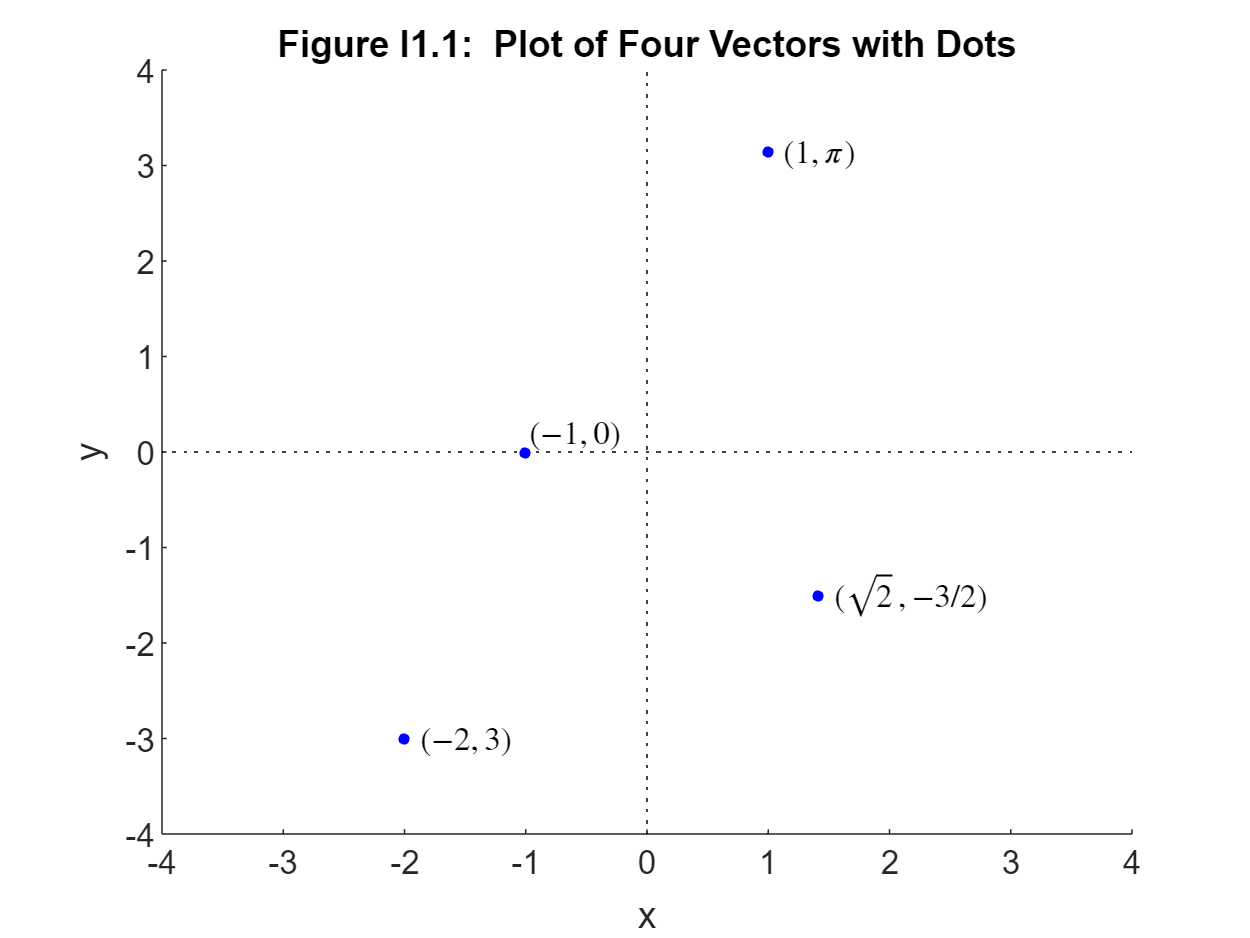

plot(x1(1),x1(2),'b.','MarkerSize',10)
text(x1(1)+d,x1(2),'$(1,\pi)$','Interpreter','latex','Color','k')
plot(x2(1),x2(2),'b.','MarkerSize',10)
text(x2(1)+d,x2(2),'$(-2,3)$','Interpreter','latex','Color','k')
plot(x3(1),x3(2),'b.','MarkerSize',10)
text(x3(1),x3(2)+2*d,'$(-1,0)$','Interpreter','latex','Color','k')
plot(x4(1),x4(2),'b.','MarkerSize',10)
text(x4(1)+d,x4(2),'$(\sqrt{2},-3/2)$','Interpreter','latex','Color','k')
title('Figure I1.1:  Plot of Four Vectors with Dots')
xlabel('x')

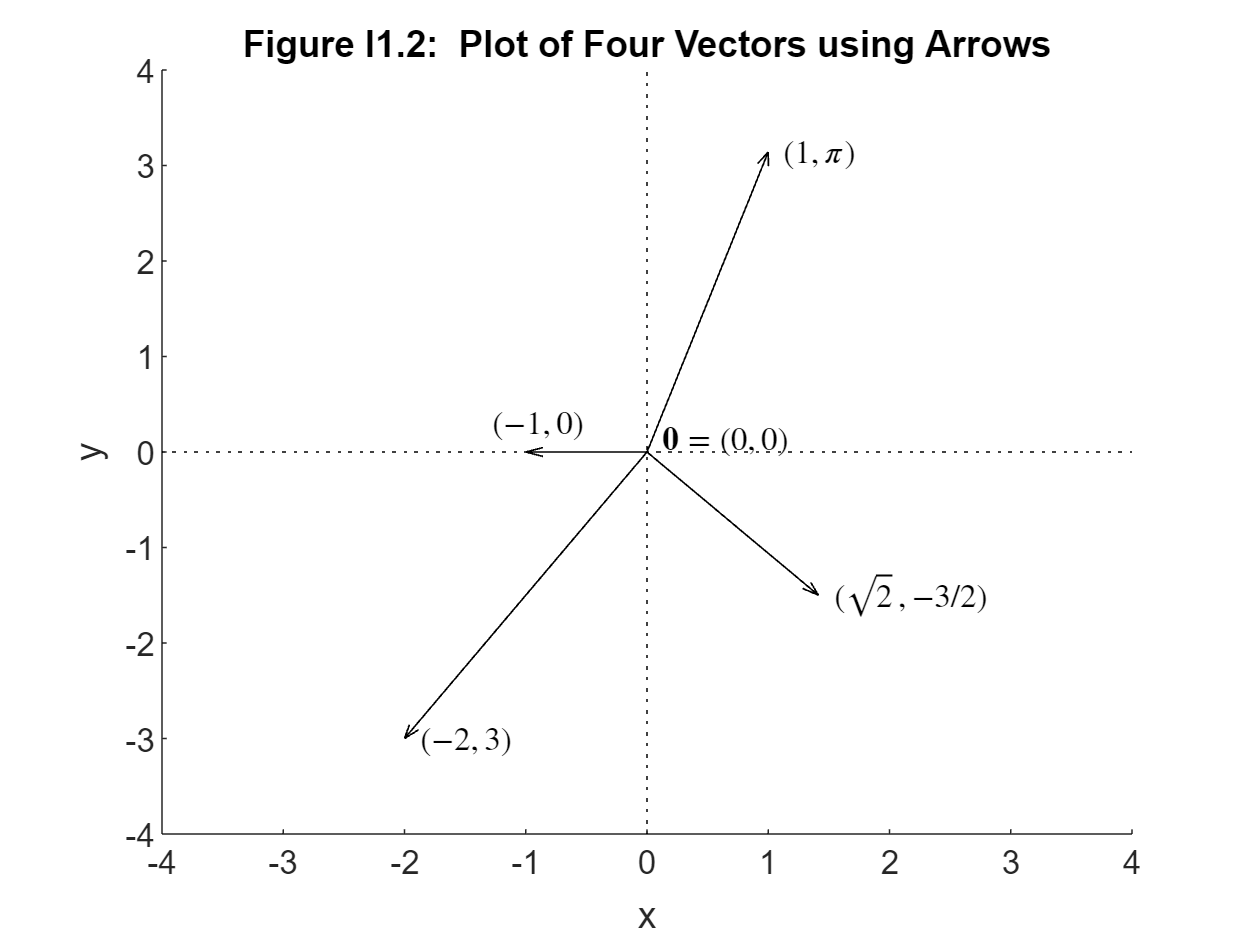

ylabel('y')
end


function figI1_2()
figure

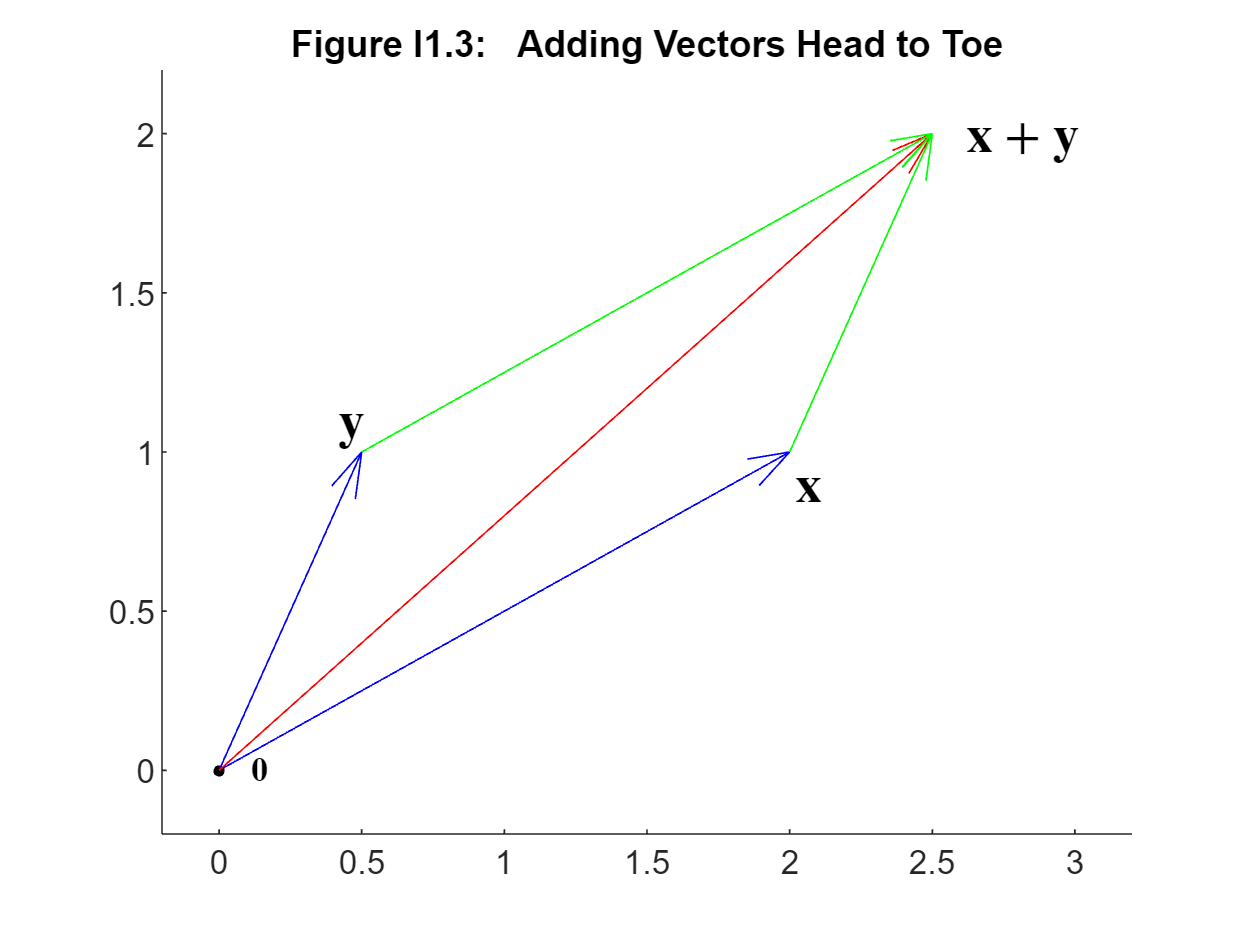

d=0.1;
L=4;
x1=[1; pi];
x2=[-2; -3];
x3=[-1; 0];

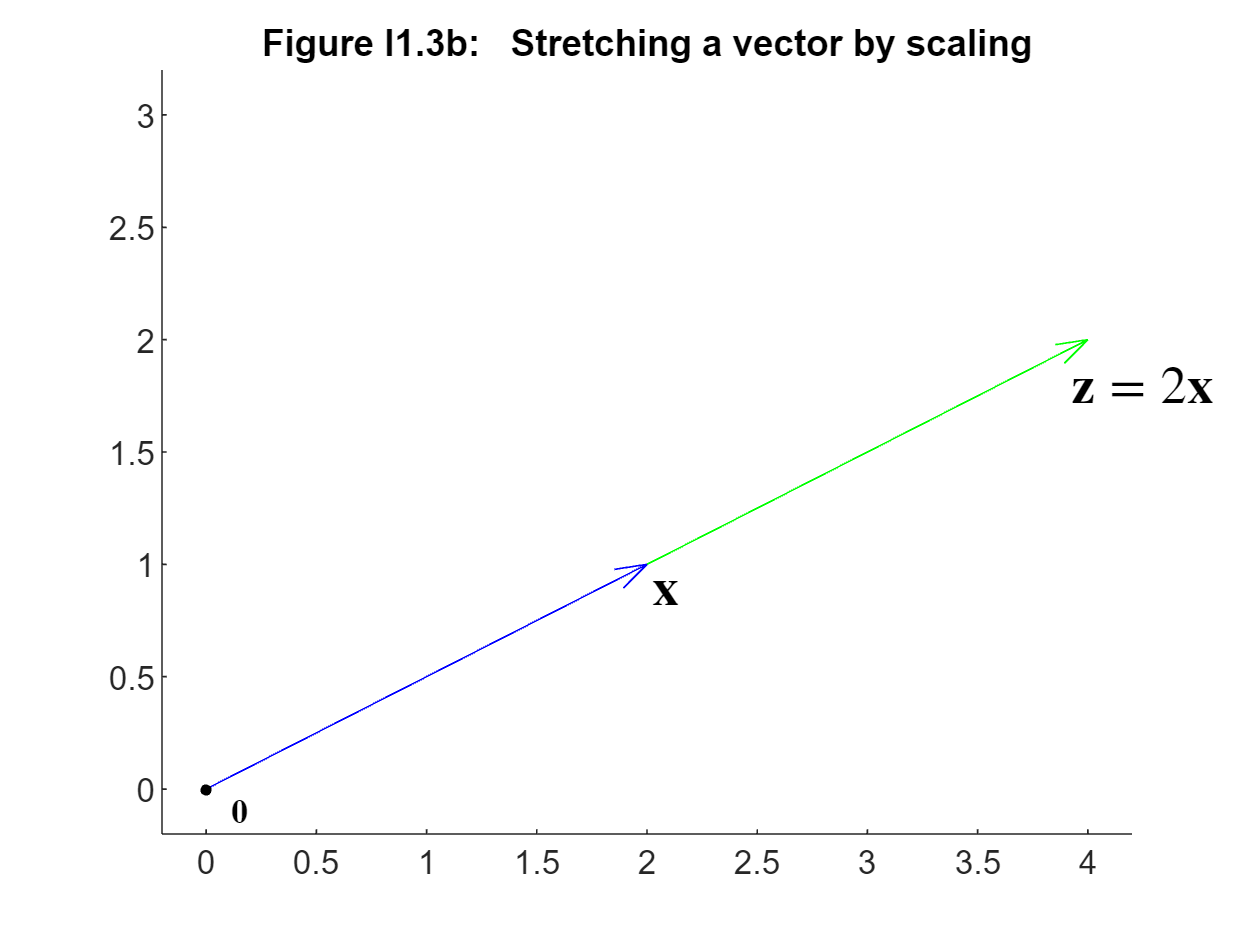

x4=[sqrt(2); -3/2];
axis([-L L -L L])
hold on
plot([-L L],[0 0],'k:')

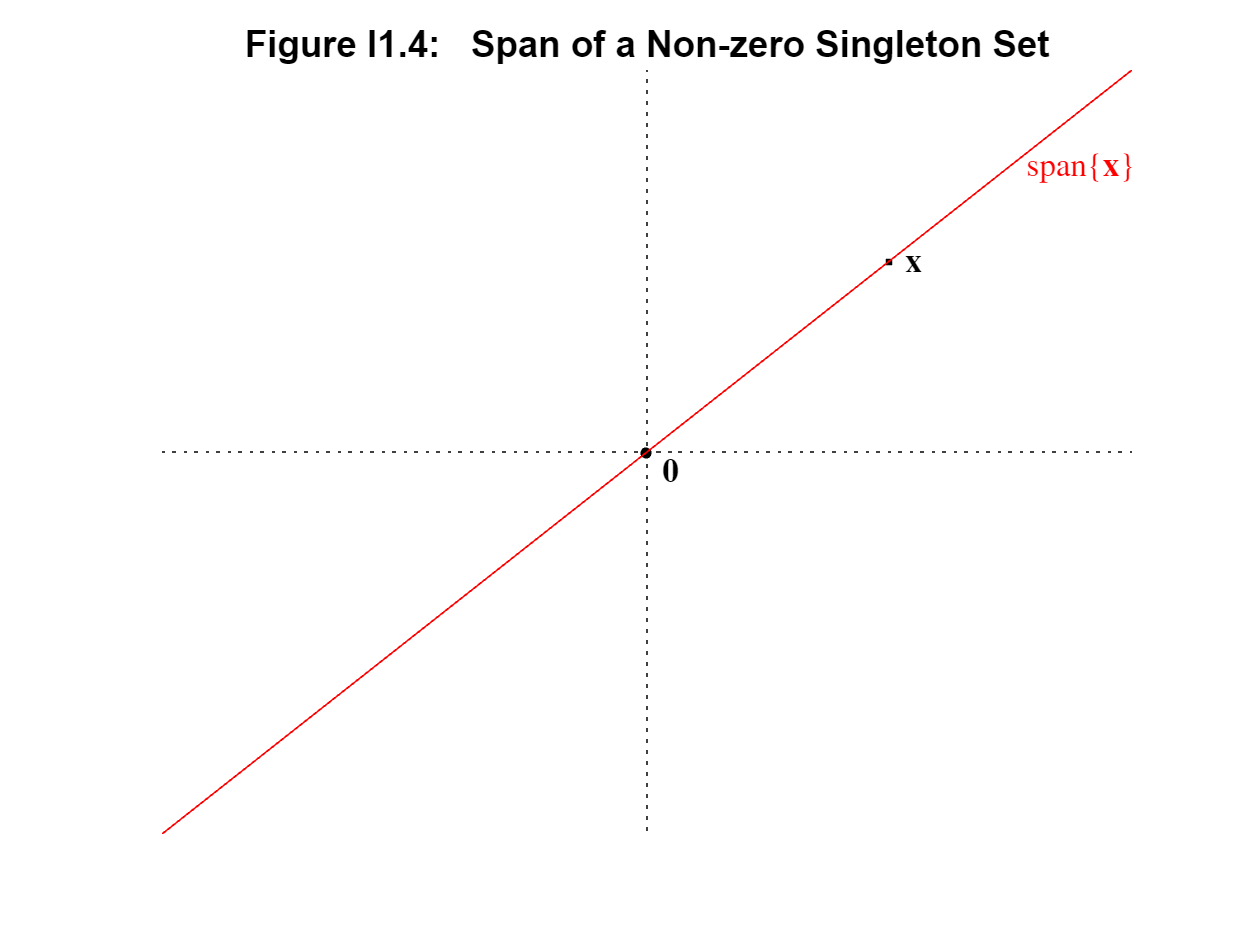

plot([0 0],[-L L],'k:')
arrow([0;0],x1,'k') 
text(x1(1)+d,x1(2),'$(1,\pi)$','Interpreter','latex','Color','k')
arrow([0;0],x2,'k')
text(x2(1)+d,x2(2),'$(-2,3)$','Interpreter','latex','Color','k')
arrow([0;0],x3,'k')
text(x3(1)-3*d,x3(2)+3*d,'$(-1,0)$','Interpreter','latex','Color','k')
arrow([0;0],x4,'k')
text(x4(1)+d,x4(2),'$(\sqrt{2},-3/2)$','Interpreter','latex','Color','k')
text(d,1.4*d,'${\bf 0}=(0,0)$','Interpreter','latex','Color','k')
title('Figure I1.2:  Plot of Four Vectors using Arrows')
xlabel('x')
ylabel('y')
end

function figI1_3()
figure
hold on
d=0.1;

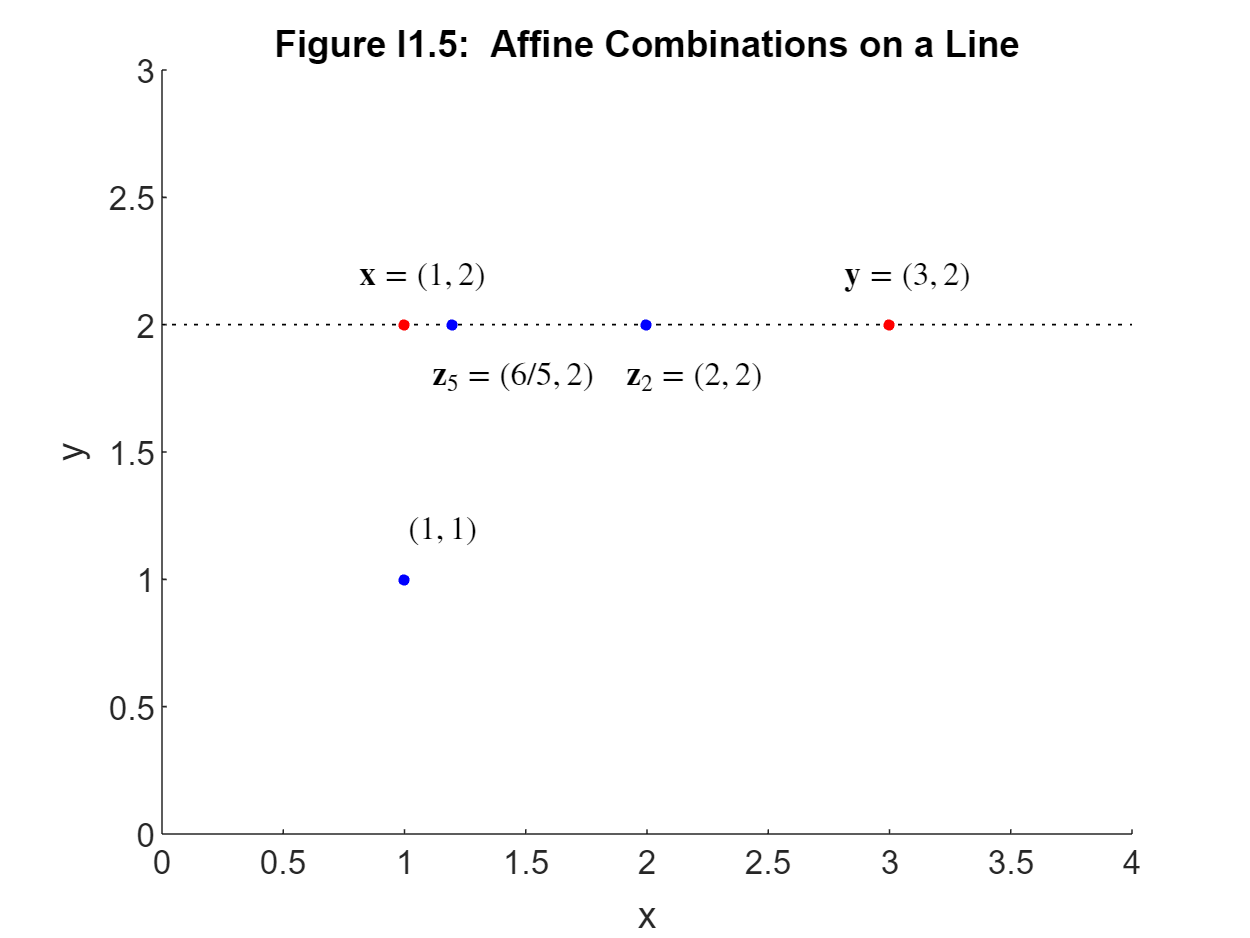

L=2.2;
axis([-1/5 L+1 -1/5 L])
x=[2; 1];
y=[1/2; 1];
z=x+y;
arrow([0;0],x,'b')
text(x(1),x(2)-d,'${\bf x}$','Interpreter','latex','FontSize',16)
text(y(1)-d,y(2)+d,'${\bf y}$','Interpreter','latex','FontSize',16)
text(d,0,'${\bf 0}$','Interpreter','latex')
plot(0,0,'.k','MarkerSize',10)
arrow([0;0],y,'b')
arrow([0;0],z,'r')
arrow(x,z,'g')
arrow(y,z,'g')
text(z(1)+d,z(2),'${\bf x}+{\bf y}$','Interpreter','latex','FontSize',16)
title('Figure I1.3:   Adding Vectors Head to Toe')
end

function figI1_3b()
figure
hold on
d=0.1;
L=3.2;
axis([-1/5 L+1 -1/5 L])
x=[2; 1];
alpha=2;
z=2*x;
arrow([0;0],z,'g')
text(z(1)-d,z(2)-2*d,'${\bf z}=2{\bf x}$','Interpreter','latex','FontSize',16)
arrow([0;0],x,'b')
text(x(1),x(2)-d,'${\bf x}$','Interpreter','latex','FontSize',16)
text(d,-d,'${\bf 0}$','Interpreter','latex')
plot(0,0,'.k','MarkerSize',10)
title('Figure I1.3b:   Stretching a vector by scaling')
end


function figI1_4()
figure
hold on
d=0.1;
L=2;
axis([-2*L 2*L -L L])
axis off
plot([-2*L 2*L],[0 0],':k')
plot([0 0],[-2*L 2*L],':k')
x=[2; 1];
plot(x(1),x(2),'.k')
text(x(1)+d,x(2),'${\bf x}$','Interpreter','latex')
plot(0,0,'.k','MarkerSize',10)
text(d,-d,'${\bf 0}$','Interpreter','latex')
plot([-2*x(1) 2*x(1)],[-2*x(2) 2*x(2)],'-r')
text(1.5*x(1)+d,1.5*x(2),'span$\{{\bf x}\}$','Interpreter','latex','Color','r')

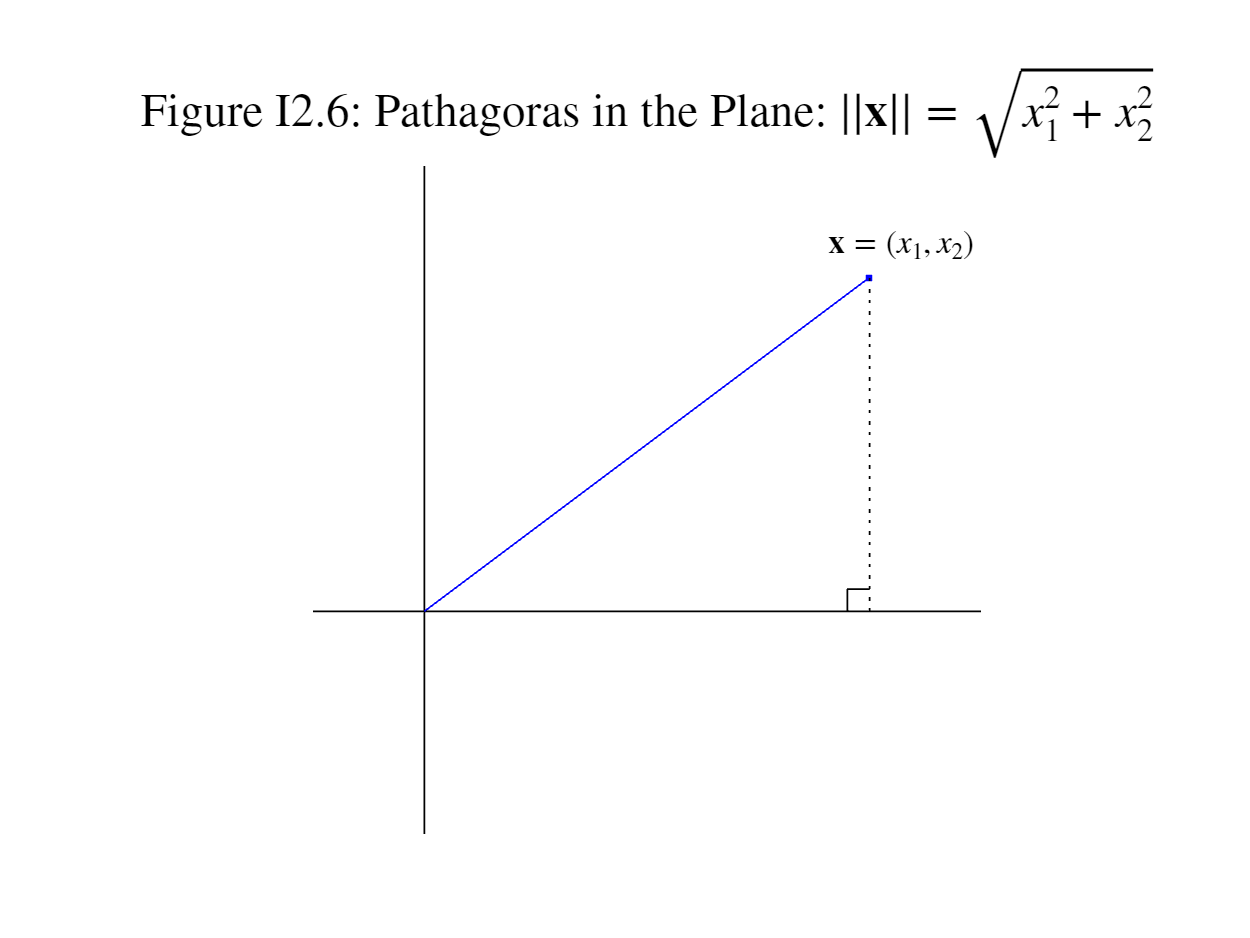

title('Figure I1.4:   Span of a Non-zero Singleton Set')
end

function figI1_5()
figure
d=0.2;
L=4;
z1=[1; 1];
z2=[2; 2];
z3=[1; 2];
z4=[3; 2];
z5=[6/5; 2];
z6=[5; 2];
axis([0 L 0 L-1])
hold on
plot([0 4],[2 2],':k')
plot(z1(1),z1(2),'b.','MarkerSize',10)
text(z1(1),z1(2)+d,'$(1,1)$','Interpreter','latex','Color','k')
plot(z2(1),z2(2),'b.','MarkerSize',10)
text(z2(1)-0.5*d,z2(2)-d,'${\bf z}_2=(2,2)$','Interpreter','latex','Color','k')
plot(z3(1),z3(2),'r.','MarkerSize',10)

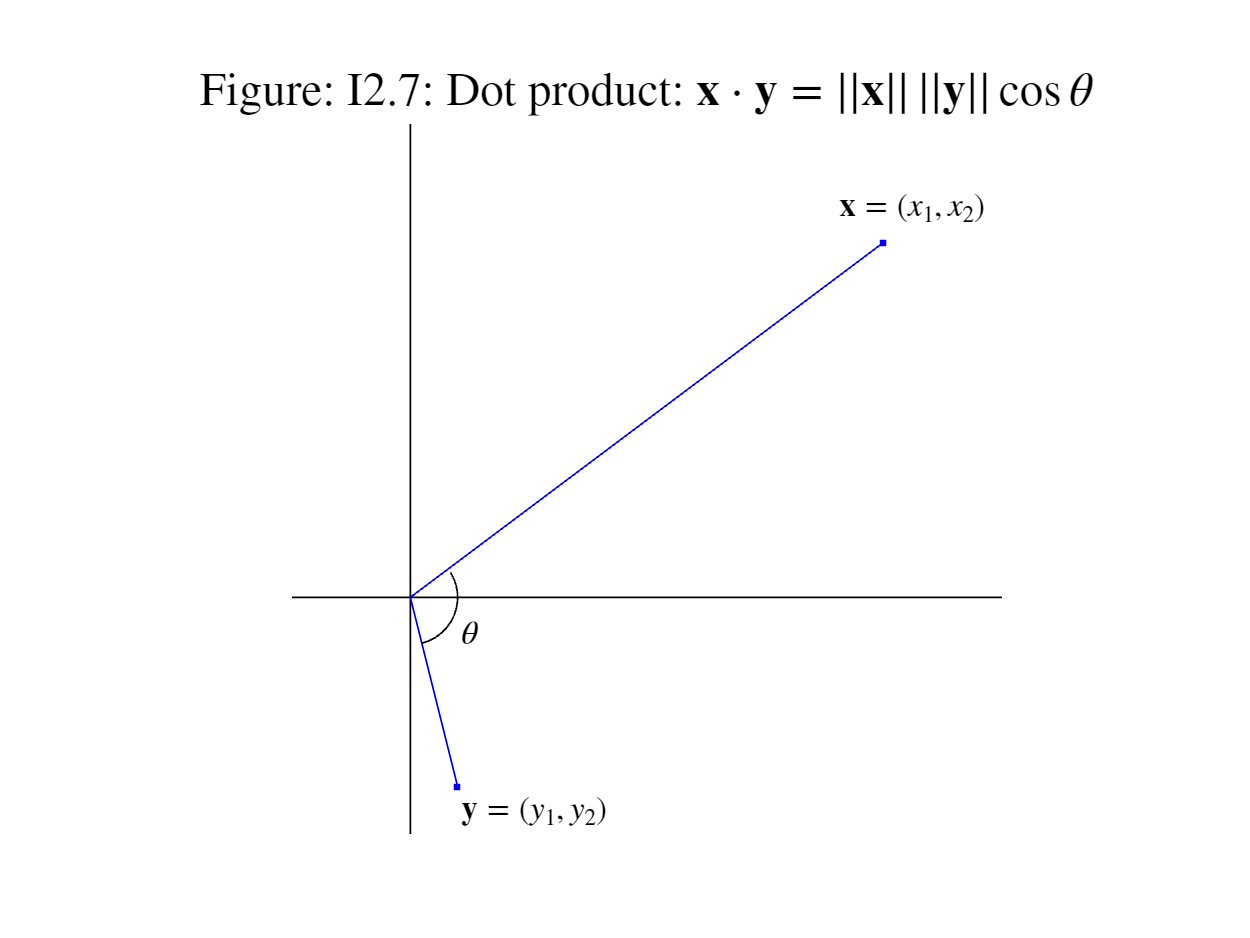

text(z3(1)-d,z3(2)+d,'${\bf x}=(1,2)$','Interpreter','latex','Color','k')
plot(z4(1),z4(2),'r.','MarkerSize',10)
text(z4(1)-d,z4(2)+d,'${\bf y}=(3,2)$','Interpreter','latex','Color','k')
plot(z5(1),z5(2),'b.','MarkerSize',10)
text(z5(1)-0.5*d,z5(2)-d,'${\bf z}_5=(6/5,2)$','Interpreter','latex','Color','k')

plot(z6(1),z6(2),'b.','MarkerSize',10)
text(z6(1),z6(2)+d,'$(5,2)$','Interpreter','latex','Color','k')
title('Figure I1.5:  Affine Combinations on a Line')
xlabel('x')
ylabel('y')
end

function figI1_6()
figure
hold on
axis off
axis equal
title(' ')
subtitle('Figure I2.6:  Pathagoras in the Plane:   $||{\bf x}||=\sqrt{x_1^2+x_2^2}$','FontSize',14,'interpreter','latex')
plot([-0.5 2.5],[0 0],'k')     % draws line from (-3,0) to (3,0) in black -- x-axis
plot([0 0],[-1 2],'k')     % draws line from (0,-3) to (0,3) in black -- y-axis
plot([0 2],[0 1.5],'b')    % draws line from (0,0) to (2,1.5) in blue -- vector of interest
plot(2,1.5,'.b')           % draws dot at (2,1.5) in blue 
text(1.8,1.65,'${\bf x}=(x_1,x_2)$','interpreter','latex')
plot([2 2],[0 1.5],':k')
plot([1.9 1.9 2.0],[0 0.1 0.1],'k')
end

function figI1_7()
figure
hold on
axis off
axis equal
title(' ')
subtitle('Figure: I2.7:  Dot product:   ${\bf x}\cdot{\bf y}=||{\bf x}||\,||{\bf y}||\cos\theta$','FontSize',14,'interpreter','latex')
plot([-0.5 2.5],[0 0],'k')     % draws line from (-3,0) to (3,0) in black -- x-axis
plot([0 0],[-1 2],'k')     % draws line from (0,-3) to (0,3) in black -- y-axis
plot([0 2],[0 1.5],'b')    % draws line from (0,0) to (2,1.5) 
plot(2,1.5,'.b')           % draws dot at (2,1.5) in blue 
text(1.8,1.65,'${\bf x}=(x_1,x_2)$','interpreter','latex')
plot([0 0.2],[0 -0.8],'b')    % draws line from (0,0) to (0.2,-0.8) 
plot(0.2,-0.8,'.b')           % draws dot at (0.2,-0.8) in blue 
text(0.2,-0.9,'${\bf y}=(y_1,y_2)$','interpreter','latex')
theta=atan(-0.8/0.2):pi/20:atan(1.5/2);
plot(0.2*cos(theta),0.2*sin(theta),'k')
text(0.2,-0.15,'$\theta$','interpreter','latex')
end

function arrow(x,y,color)
% draws arrow from x to y in the given color
f=0.15;
plot([x(1) y(1)],[x(2) y(2)],'-','Color',color)
theta=pi/10;
R=[cos(theta) -sin(theta); sin(theta) cos(theta)];
ah1= -R*(y-x);
r=sqrt(ah1(1)*ah1(1)+ah1(2)*ah1(2));
plot([y(1) y(1)+f*ah1(1)/r],[y(2) y(2)+f*ah1(2)/r],'Color',color)
ah2= -R'*[y-x];
plot([y(1) y(1)+f*ah2(1)/r],[y(2) y(2)+f*ah2(2)/r],'Color',color)
end



